# **Lab 5**

#### Objective:

The objective of this lab is to create an understanding of convolution by writing a  code to perform convolution of two signals.

#### Theoretical Background: 

Convolution is the representation of an LTI system in terms of its unit impulse  response. Impulse response of a system h[n] is the output when a unit impulse δ[n] is  given at its input. For a system with input x[n] and the system impulse response h[n],  the output y[n] of the system is calculated by convolution of the system response and  input, given as: 

𝑦[𝑛] = 𝑥[𝑛] ∗ ℎ[𝑛] 

#### Tasks:

Write your own code for convolution of the following sets of discrete sequences,  such that the convolved signal y[n] is given as described above. Explain each and  every step in your code. Compare your results with the results of built in conv  function

#### **Task 1:**

When x[n] is a unit impulse and h[n] is a unit step function. 

% Define the unit impulse function δ[n]
n = -10:10;
x = (n == 0);

% Define the unit step function u[n]
h = (n >= 0);

m = length(x);
o = length(h);
k = m + o - 1;

% Initialize y_manual and y_conv as arrays of zeros
y_manual = zeros(1, k);
y_conv = zeros(1, k);

% Perform convolution manually using nested loops
for i = 1:k
    for j = 1:m
        if i - j + 1 > 0 && i - j + 1 <= o
            y_manual(i) = y_manual(i) + x(j) * h(i - j + 1);
        end
    end
end

y_manual

y_manual =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     1     1     1     1     1     1     1     1     1     1     1     0     0     0     0     0     0     0     0     0     0



% Perform convolution using the built-in 'conv' function
y_conv = conv(x, h)

y_conv =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     1     1     1     1     1     1     1     1     1     1     1     0     0     0     0     0     0     0     0     0     0



% Compare the results
isequal(y_manual, y_conv) % Check if the results are equal

ans = logical
   1


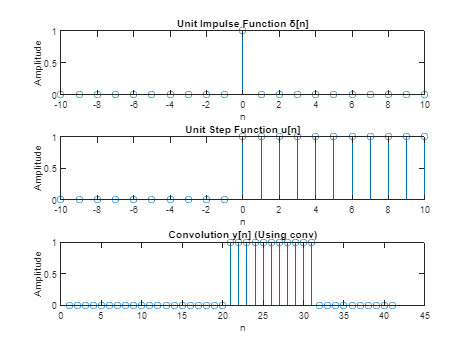


% Plot the signals and their convolution result
subplot(3, 1, 1);
stem(n, x);
title('Unit Impulse Function δ[n]');
xlabel('n');
ylabel('Amplitude');

subplot(3, 1, 2);
stem(n, h);
title('Unit Step Function u[n]');
xlabel('n');
ylabel('Amplitude');

z =  1: k;

subplot(3, 1, 3);
stem(z, y_conv);
title('Convolution y[n] (Using conv)');
xlabel('n');
ylabel('Amplitude');

#### Task 2:

When both x[n] and h[n] are unit step functions. 

% Define the unit step function u[n] one
n = -10:10;
x = (n >= 0); 

% Define the unit step function u[n] two
h = (n >= 0);

m = length(x);
o = length(h);
k = m + o - 1;

% Initialize y_manual and y_conv as arrays of zeros
y_manual = zeros(1, k);
y_conv = zeros(1, k);

% Perform convolution manually using nested loops
for i = 1:k
    for j = 1:m
        if i - j + 1 > 0 && i - j + 1 <= o
            y_manual(i) = y_manual(i) + x(j) * h(i - j + 1);
        end
    end
end

y_manual;

% Perform convolution using the built-in 'conv' function
y_conv = conv(x, h);

% Compare the results
isequal(y_manual, y_conv) % Check if the results are equal

ans = logical
   1


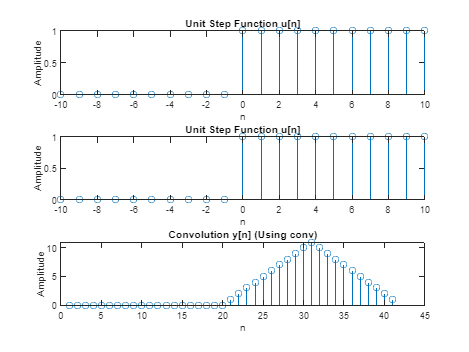


% Plot the signals and their convolution result
subplot(3, 1, 1);
stem(n, x);
title('Unit Step Function u[n]');
xlabel('n');
ylabel('Amplitude');

subplot(3, 1, 2);
stem(n, h);
title('Unit Step Function u[n]');
xlabel('n');
ylabel('Amplitude');

z =  1: k;

subplot(3, 1, 3);
stem(z, y_conv);
title('Convolution y[n] (Using conv)');
xlabel('n');
ylabel('Amplitude');

#### Task 3:

When 𝑥[𝑛] = (0.5) 𝑛 𝑢[𝑛] and h[n] is a unit step function. 

% Define the unit step function u[n]
n = -10:10;
h = (n >= 0);

% Define x[n]
x = (0.5).^n .* (n >= 0);

m = length(x);
o = length(h);
k = m + o - 1;

% Initialize y_manual and y_conv as arrays of zeros
y_manual = zeros(1, k);
y_conv = zeros(1, k);

% Perform convolution manually using nested loops
for i = 1:k
    for j = 1:m
        if i - j + 1 > 0 && i - j + 1 <= o
            y_manual(i) = y_manual(i) + x(j) * h(i - j + 1);
        end
    end
end

y_manual;

% Perform convolution using the built-in 'conv' function
y_conv = conv(x, h);

% Compare the results
isequal(y_manual, y_conv) % Check if the results are equal

ans = logical
   1


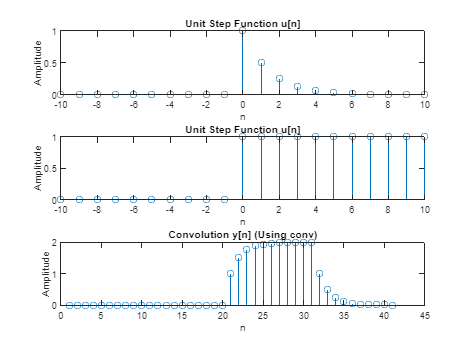


% Plot the signals and their convolution result
subplot(3, 1, 1);
stem(n, x);
title('Unit Step Function u[n]');
xlabel('n');
ylabel('Amplitude');

subplot(3, 1, 2);
stem(n, h);
title('Unit Step Function u[n]');
xlabel('n');
ylabel('Amplitude');

z =  1: k;

subplot(3, 1, 3);
stem(z, y_conv);
title('Convolution y[n] (Using conv)');
xlabel('n');
ylabel('Amplitude');